addpath('C:\Users\jdama\Documents\CV_Challenge\2.Programming\Computer_vision_challenge\src'); 

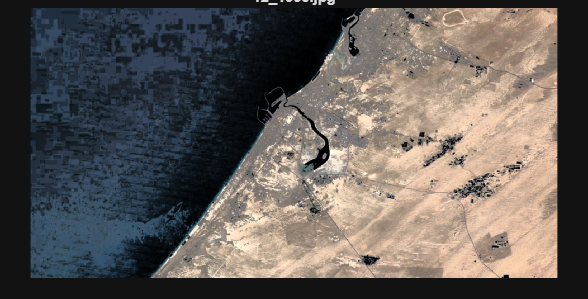

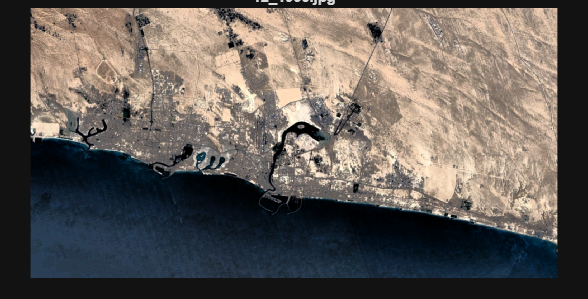

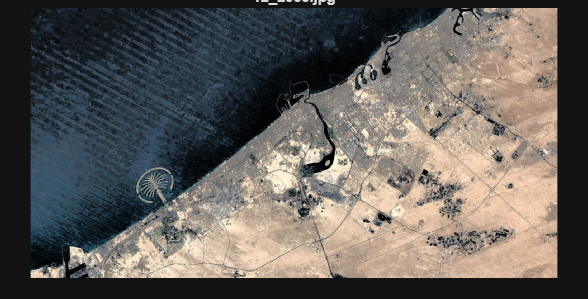

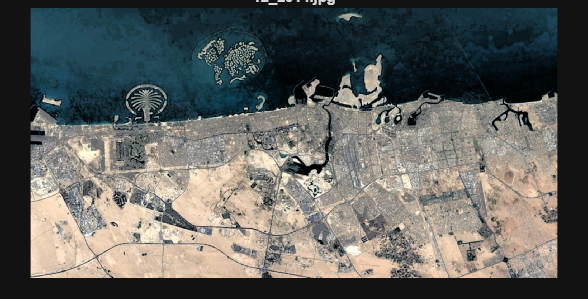

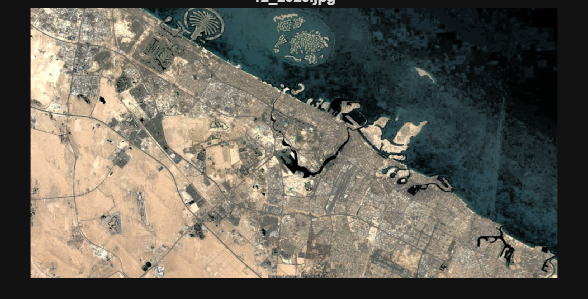

% Select folder with test images
folder_path = uigetdir([], 'Wähle den Ordner mit Bildern');

%  Get all files
files = dir(folder_path);
imagePaths = {};

for i = 1:length(files)
    if ~files(i).isdir
        imagePaths{end+1} = fullfile(folder_path, files(i).name);
    end
end

% Call your updated preprocess_images function
preprocessed = preprocess_images(imagePaths);

% Show results
for i = 1:length(preprocessed)
    figure;
    imshow(preprocessed(i).image);
    title(preprocessed(i).name, 'Interpreter', 'none');
end